clear all;
close all;
clc;

## READ AUDIO FILE


[xn,fs] = audioread('sample_audio_file.wav');
% convert from stero to mono 
xn = mean(xn,2);
N_xn = length(xn);
% axis of drawing 
t = linspace(0, N_xn/fs ,N_xn);
% divided by fs or N ? 
xf = abs(fft(xn)) / N_xn;
%xf = xf(1:N/2);
f = linspace(0, fs ,N_xn);

## DIGITAL ECHO SYSTEM

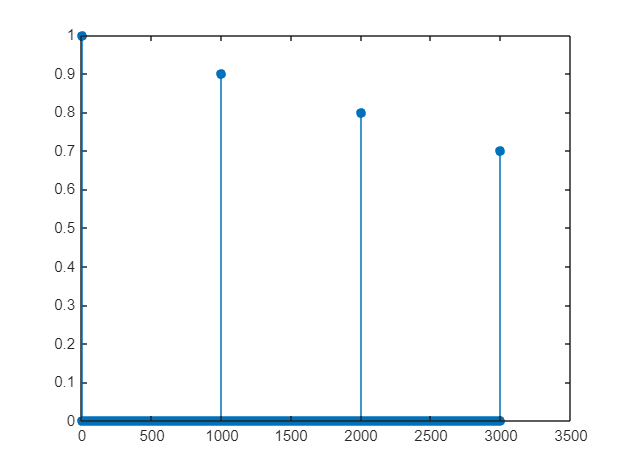


hn = zeros(1,3001);
D = 1000 ;
hn(1) = 1 ; 
hn(1*D+1) = 0.9 ;
hn(2*D+1) = 0.8 ;
hn(3*D+1) = 0.7 ;

%  Filter’s Impulse Response
N_DFTH = 1024;
N_DFT = 8192; % N-DFT
n = linspace(1,length(hn),length(hn));
figure
stem(n,hn,"filled");

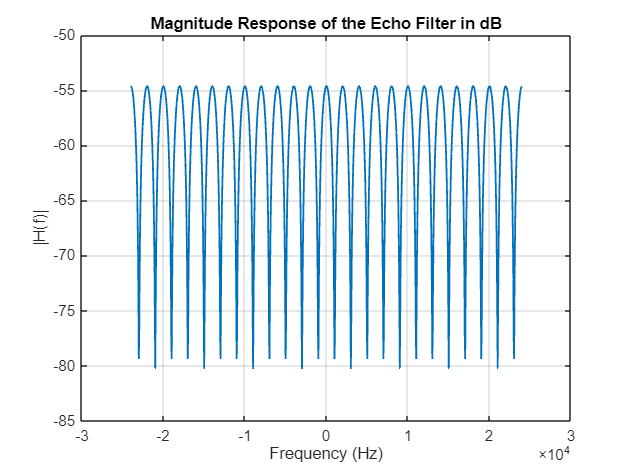

% we should implement the group delay !!!! 

% Magnitude and phase response of the filter in dB

% Magnitude in dB 
Hf = fftshift( fft(hn, N_DFTH) / N_DFTH );
Hfmag = 20*log10(abs(Hf));
f = linspace(-fs/2, fs/2 ,N_DFTH); 
figure;
plot(f, Hfmag, 'LineWidth',1.2)
xlabel('Frequency (Hz)');
ylabel('|H(f)|');
title('Magnitude Response of the Echo Filter in dB');
grid on;

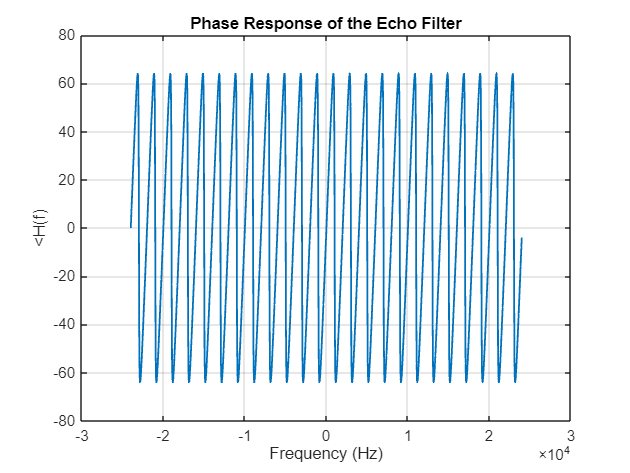


% phase plot 
Hfdegree = angle(Hf) * (180/pi) ; 
figure;
plot(f, Hfdegree, 'LineWidth',1.2)
xlabel('Frequency (Hz)');
ylabel('<H(f)');
title('Phase Response of the Echo Filter');
grid on;

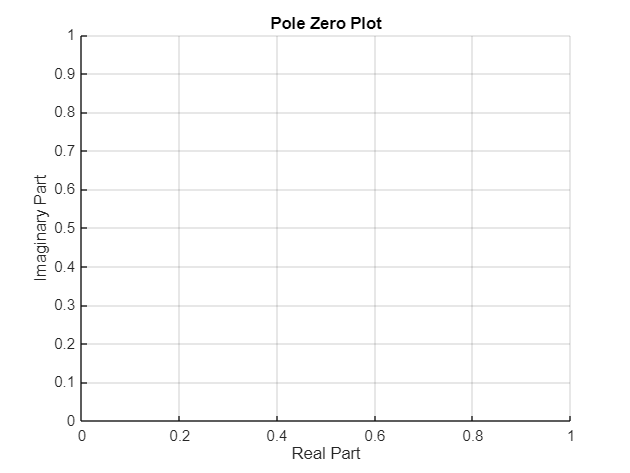

% P-Z plot 
figure 
%zplane(hn,1);
xlabel('Real Part');
ylabel('Imaginary Part');
title('Pole Zero Plot');
grid on;

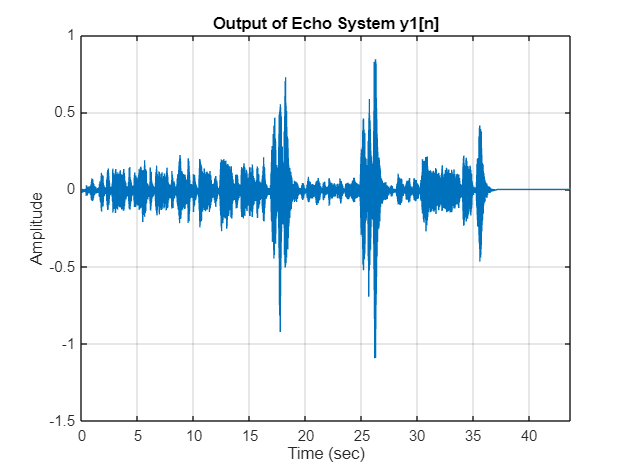

%using x[n] is an input to the echo system
y1n = conv(hn,xn);
audio_echo = audioplayer(real(y1n), fs);
%playblocking(audio_echo);
figure
plot(t,y1n(1:N_xn))
grid on
title('Output of Echo System y1[n]')
xlabel('Time (sec)')
ylabel('Amplitude')
xlim([0, N_xn/fs])

## MSE for Y1


MSE1 = (1/(N_xn+1)) * sum((y1n(1:N_xn)-xn).^2)

MSE1 = 0.0019

## EQUALIZER

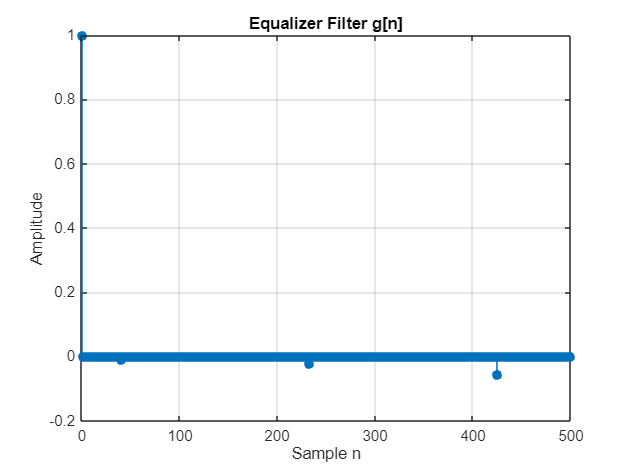


Hf_eq = fft(hn, N_DFT);
Gf = 1 ./ (Hf_eq );
gn = real(ifft(Gf));
gn = gn(1:length(hn));

% Plot equalizer g[n]
figure;
stem(1:length(gn), gn, 'filled');
title('Equalizer Filter g[n]');
xlabel('Sample n');
ylabel('Amplitude');
grid on;
xlim([0 500]); 

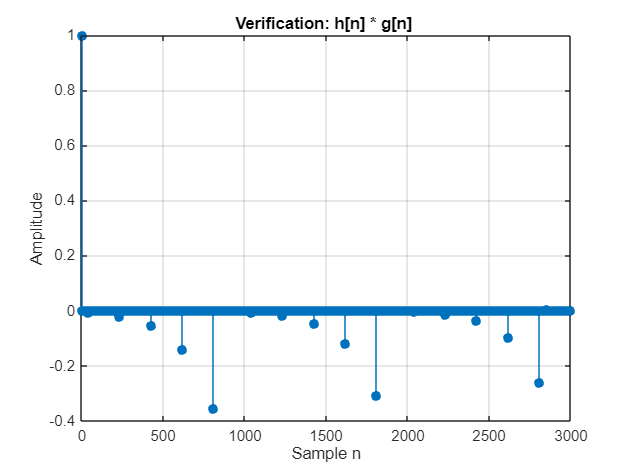

% Verify: h[n] * g[n] should approximate delta[n]
verification = conv(hn, gn);
figure;
stem(1:length(verification), verification, 'filled');
title('Verification: h[n] * g[n] ');
xlabel('Sample n');
ylabel('Amplitude');
grid on;
xlim([0 3000]);

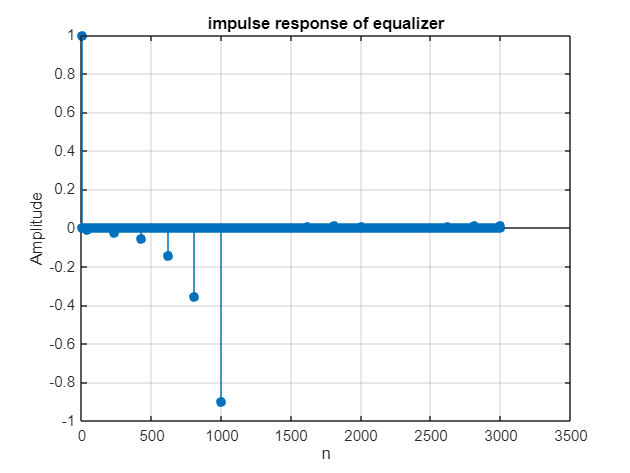

delta = zeros(1,length(gn));
delta(1) = 1;
impulse_g = conv(delta,gn);
stem(1:length(gn), impulse_g(1:length(gn)), 'filled');
title('Impulse response of equalizer');
xlabel('n');
ylabel('Amplitude');
grid on;

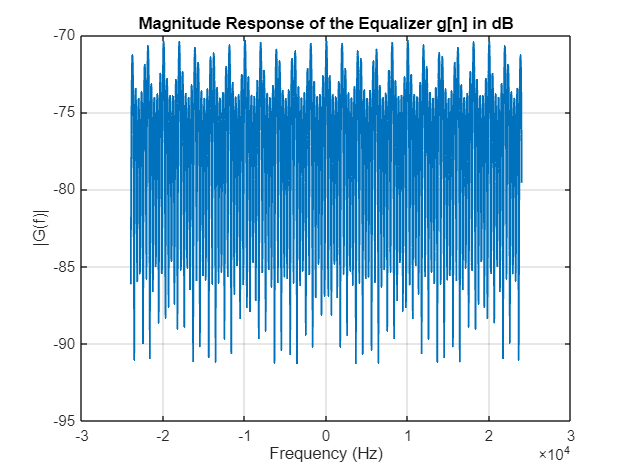



% Frequency response of equalizer
Gf_plot = fftshift(fft(gn, N_DFT) / N_DFT);
Gfmag = 20*log10(abs(Gf_plot));
f_plot = linspace(-fs/2, fs/2, N_DFTH);

figure;
plot(f_plot, Gfmag(1:N_DFTH), 'LineWidth', 1.2)
xlabel('Frequency (Hz)');
ylabel('|G(f)|');
title('Magnitude Response of the Equalizer g[n] in dB');
grid on;

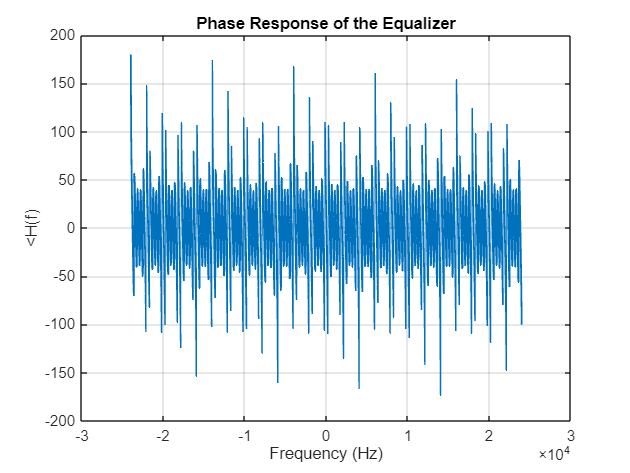

% phase plot 
Gfdegree = angle(Gf_plot) * (180/pi) ; 
figure;
plot(f_plot, Gfdegree(1:N_DFTH), 'LineWidth',1.2)
xlabel('Frequency (Hz)');
ylabel('<H(f)');
title('Phase Response of the Equalizer');
grid on;

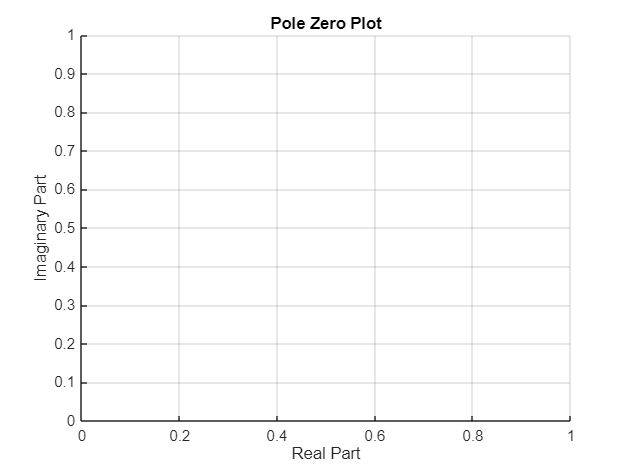

% P-Z plot 
figure 
%zplane(1,hn);
xlabel('Real Part');
ylabel('Imaginary Part');
title('Pole Zero Plot');
grid on;

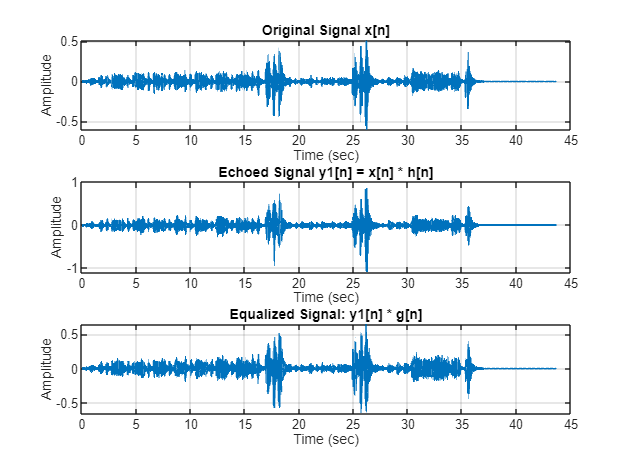



%% Apply equalizer to echoed signal
y1n_equalized = conv(y1n, gn);
y1n_equalized = y1n_equalized(1:N_xn);

%% Comparison plots
figure;
subplot(3,1,1);
plot(t, xn, 'LineWidth', 1.2);
title('Original Signal x[n]');
xlabel('Time (sec)');
ylabel('Amplitude');
grid on;

subplot(3,1,2);
plot(t, y1n(1:N_xn), 'LineWidth', 1.2);
title('Echoed Signal y1[n] = x[n] * h[n]');
xlabel('Time (sec)');
ylabel('Amplitude');
grid on;

subplot(3,1,3);
plot(t, y1n_equalized, 'LineWidth', 1.2);
title('Equalized Signal: y1[n] * g[n]');
xlabel('Time (sec)');
ylabel('Amplitude');
grid on;

## MSE FOR Y2


 audio_equalized = audioplayer(real(y1n), fs);
 %playblocking(audio_equalized);
 MSE2 = (1/(N_xn+1)) * sum((y1n_equalized(1:N_xn)-xn).^2)

MSE2 = 6.6801e-04


 % kol el normalization
 % impulse response of equalizer 
 % Group delay 
 % phase response in db??????
 % hsabat el energy
 